# Ecuaciones diferenciales de orden superior

## Resolver ecuaciones diferenciales de segundo orden de forma analítica:


$$y'' + 2y' + y = 0;$$
      
$$y(0) = 5,$$
      
$$y'(0) = -3;$$


syms y(t) x(t) t

dy = diff(y, t);
d2y = diff(y, t, 2);

y0 = 5;
dy0 = -3;

y(t) = dsolve(d2y==-2*dy-y, y(0)==y0, dy(0)==dy0)

$$y(t) = {\mathrm{e}}^{-t}\,\left(2\,t+5\right)$$

tt = linspace(0, 10);
yy = y(tt);

x(t) = diff(y, t);
xx = x(tt);

plot(tt, yy, 'b', tt, xx, 'r');
legend('y(t)', 'x(t)', 'Location','best')
grid on;

## Ahora se resuelve de forma numérica:


$$y'' + 2y' + y = 0;$$
      
$$y(0) = 5,$$
      
$$y'(0) = -3;$$


Entonces, se reduce el orden de la ecuación de tal forma que:


$$x=y^{\prime } \;\;\;\;\;\;\;\;x^{\prime } =y^{\prime \prime }$$


Llegando a al siguiente sistema de ecuaciones diferenciales:


$${y^{\prime } =x\;\;\;\;\;\;\;\;\;\;\;\;x}^{\prime } =-2x-y$$


fg = @(t, yx) [(yx(2)); (-2.*yx(2) - yx(1))];

t0 = 0;
tf = 10;

y0 = 5;
x0 = -3;

[t, yx] = ode45(fg, [t0 tf], [y0; x0]);

y = yx(:, 1);
x = yx(:, 2);

plot(t, y, 'b', t, x, 'r');
legend('y(t)', 'x(t)', 'Location','best')
grid on;

También se puede modelar un sistema masa resorte amortiguado:


$$m\frac{d^2 }{\mathrm{d}t^2 }x+b\frac{d}{\mathrm{d}t}x+kx=f$$



$$\ddot{x} =\frac{1}{m}f-\frac{b}{m}\dot{x} -\frac{k}{m}x$$



$$\begin{array}{l}
f\left(t\right)=e^{-t} \;N\;\;\;\;\;\;m=0\ldotp 5\;\mathrm{kg}\;\;\;\;\;\;\;\;\;\;\;\;b=0\ldotp 02\;\frac{\mathrm{kg}}{s}\;\;\;\;\;\;\;\;\;\;k=0\ldotp 05\;\frac{\mathrm{kg}}{s^2 }\\
x\left(0\right)=0\;m\;\;\;\;\;\;v\left(0\right)=1\;\frac{m}{s}
\end{array}$$


syms x(t) t

f = exp(-t);
m = 0.5;
b = 0.02;
k = 0.05;

x0 = 0;
dx0 = 1;

dx = diff(x, t);
d2x = diff(x, t, 2);

x(t) = dsolve(d2x == (1/m)*f - (b/m)*dx - (k/m)*x, x(0) == x0, dx(0) == dx0)

$$x(t) = \frac{50\,{\mathrm{e}}^{-t}\,\left(498\,{\cos\left(\frac{\sqrt{249}\,t}{50}\right)}^{2}-498\,{\mathrm{e}}^{\frac{49\,t}{50}}\,\cos\left(\frac{\sqrt{249}\,t}{50}\right)+498\,{\sin\left(\frac{\sqrt{249}\,t}{50}\right)}^{2}+151\,\sqrt{249}\,{\mathrm{e}}^{\frac{49\,t}{50}}\,\sin\left(\frac{\sqrt{249}\,t}{50}\right)\right)}{13197}$$

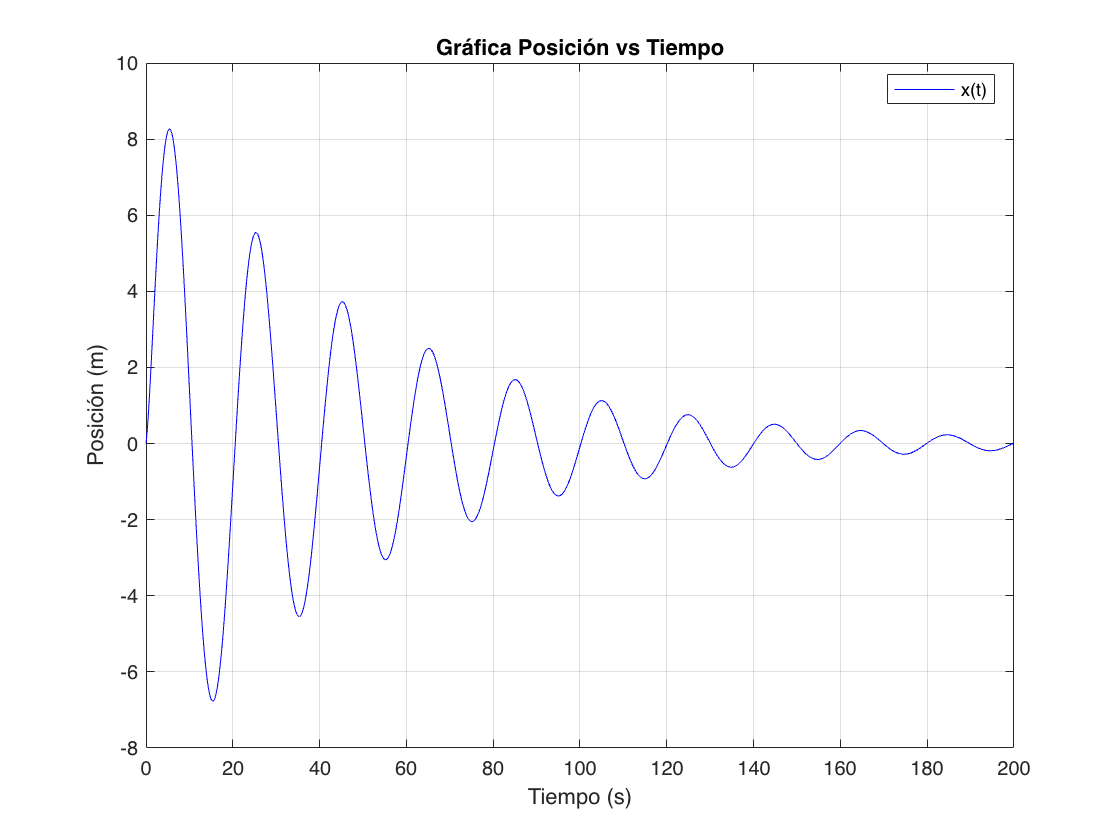

tt = linspace(0, 200, 2000);
xx = x(tt);

plot(tt, xx, 'b')
title('Gráfica Posición vs Tiempo')
legend('x(t)', 'Location', 'best')
xlabel('Tiempo (s)')
ylabel('Posición (m)')
grid on;

# Sistemas de ecuaciones diferenciales ordinarias de primer orden


$$\frac{d}{\mathrm{d}t}x=2x+4y$$
         
$$\frac{d}{\mathrm{d}t}y=-x+6y$$



$$x\left(0\right)=-1\;\;\;\;\;y\left(0\right)=6$$


## Resolviendo el sistema de ecuaciones diferenciales de forma analítica

syms t x(t) y(t)

dx = diff(x, t);
dy = diff(y, t);

x0 = -1;
y0 = +6;

S = dsolve(dx==2*x+4*y, dy==-x+6*y, x(0)==x0, y(0)==y0);
x(t) = S.x

$$x(t) = 26\,t\,{\mathrm{e}}^{4\,t}-{\mathrm{e}}^{4\,t}$$

y(t) = S.y

$$y(t) = 6\,{\mathrm{e}}^{4\,t}+13\,t\,{\mathrm{e}}^{4\,t}$$

tt = linspace(0, 0.6);
xx = x(tt);
yy = y(tt);

plot(tt, xx, 'r', tt, yy, 'b');
legend('x(t)', 'y(t)', 'Location','best')
grid on;

## Resolviendo el sistema de ecuaciones diferenciales de forma numérica

fg = @(t, xy) [(2.*xy(1) + 4.*xy(2)); (-1.*xy(1) + 6.*xy(2))];

t0 = 0.0;
tf = 0.6;
x0 = -1;
y0 = +6;

[t, xy] = ode45(fg, [t0 tf], [x0; y0]);

x = xy(:, 1);
y = xy(:, 2);

plot(t, x, 'r', t, y, 'b');
legend('x(t)', 'y(t)', 'Location','best')
grid on;